data = load("../HMP_Dataset/Climb_stairs/Accelerometer-2011-03-24-10-24-39-climb_stairs-f1.txt");
data2 = load()

## Data loaded and now we define a function for conversion and apply it to

the data

x = data(:,1);
y = data(:,2);
z = data(:,3);

plot_data(x,y,z,'Before conversion');

x = convert(data(:,1));
y = convert(data(:,2));
z = convert(data(:,3));

plot_data(x,y,z,'After conversion');

## Next is to set up the sampling

need a cosine signal cos(2*pi*f*t)

t = linspace(-0.5,0.5,length(x));
c = (@(f,t) cos(2*pi*f*t));

c_discrete();


% this plot shows the cos using the first 100 frequencies. uncomment code
% below to see the plot
%figure(Visible="on",Name='custom cos')
% for i = 1:1e2
%     plot(t,c(i,t));
%     plot_title = sprintf('freq = %.2f',i);
%     title(plot_title)
%     pause(.1)
% end

% from the MANUAL.txt file included in the data. 
figure
% example sampling freq of data we have
Fs = 32

Fs = 32

% the span of time/period gives the number of samples we have in the data.
% assuming we have N samples in the data, the span would be N*period
N =300

N = 300

t_span = N*(1/Fs)

t_span = 9.3750


t = 0:t_span/N:t_span

t =          0    0.0312    0.0625    0.0938    0.1250    0.1562    0.1875    0.2188    0.2500    0.2812    0.3125    0.3438    0.3750    0.4062    0.4375    0.4688    0.5000    0.5312    0.5625    0.5938    0.6250    0.6562    0.6875    0.7188    0.7500    0.7812    0.8125    0.8438    0.8750    0.9062    0.9375    0.9688    1.0000    1.0312    1.0625    1.0938    1.1250    1.1562    1.1875    1.2188    1.2500    1.2812    1.3125    1.3438    1.3750    1.4062    1.4375    1.4688    1.5000    1.5312


% the frequencies we will test for the sampling
freq = .1:.1:64

freq =     0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000    2.1000    2.2000    2.3000    2.4000    2.5000    2.6000    2.7000    2.8000    2.9000    3.0000    3.1000    3.2000    3.3000    3.4000    3.5000    3.6000    3.7000    3.8000    3.9000    4.0000    4.1000    4.2000    4.3000    4.4000    4.5000    4.6000    4.7000    4.8000    4.9000    5.0000


% their periods are 1/freq
Ts = freq.^(-1)

Ts =    10.0000    5.0000    3.3333    2.5000    2.0000    1.6667    1.4286    1.2500    1.1111    1.0000    0.9091    0.8333    0.7692    0.7143    0.6667    0.6250    0.5882    0.5556    0.5263    0.5000    0.4762    0.4545    0.4348    0.4167    0.4000    0.3846    0.3704    0.3571    0.3448    0.3333    0.3226    0.3125    0.3030    0.2941    0.2857    0.2778    0.2703    0.2632    0.2564    0.2500    0.2439    0.2381    0.2326    0.2273    0.2222    0.2174    0.2128    0.2083    0.2041    0.2000



% the number of samples we would get in the range is then the floor of the
% span of time / period in the test sampling freq
n_s = floor(t_span./Ts)+1

n_s =      0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    45    46


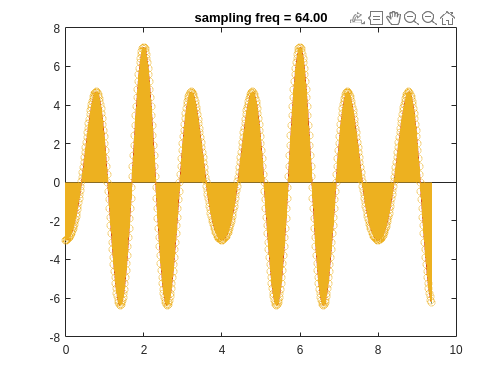



%plotting now every test freq we have in sample data
for i = 1:1:length(freq)
    % plotting the real signal
    plot(t,2*cos(2*pi*t)-5*cos(3*pi/2 *t));
    hold on;
    % the sampled signal overlayed with the real one
    t_s = 0:t_span/n_s(i):(t_span - 1/n_s(i));
    plot(t_s, 2*cos(2*pi*t_s)-5*cos(3*pi/2 *t_s));
    stem(t_s, 2*cos(2*pi*t_s)-5*cos(3*pi/2 *t_s));
    title(sprintf("sampling freq = %.2f",freq(i)))
    hold off;
    pause(.01)
end

n_s = floor(t_span./Ts)+1

n_s =      1     2     3     4     5     6     6     7     8     9    10    11    11    12    13    14    15    16    17    17    18    19    20    21    22    22    23    24    25    26    27    28    28    29    30    31    32    33    33    34    35    36    37    38    38    39    40    41    42    43



% example sampling freq of data we have
Fs = 32

Fs = 32

% the span of time/period gives the number of samples we have in the data.
N = length(x)

N = 270

t_span = N*(1/Fs)

t_span = 8.4375

t = 0:t_span/N:(t_span-1/Fs)

t =          0    0.0312    0.0625    0.0938    0.1250    0.1562    0.1875    0.2188    0.2500    0.2812    0.3125    0.3438    0.3750    0.4062    0.4375    0.4688    0.5000    0.5312    0.5625    0.5938    0.6250    0.6562    0.6875    0.7188    0.7500    0.7812    0.8125    0.8438    0.8750    0.9062    0.9375    0.9688    1.0000    1.0312    1.0625    1.0938    1.1250    1.1562    1.1875    1.2188    1.2500    1.2812    1.3125    1.3438    1.3750    1.4062    1.4375    1.4688    1.5000    1.5312



freq = 2:1:640

freq =      2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50    51


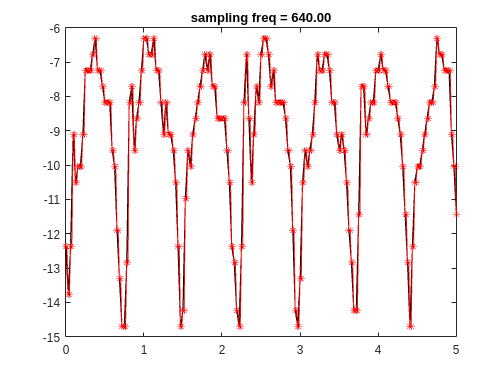

figure

for i = freq
    t_s = 0:t_span/n_s(i-1):(t_span - 1/n_s(i-1));
    
    abs_diff = abs(t(:) - t_s(:).');
    % Find the index of the minimum absolute difference for each element in vec2
    [~, closest_indices] = min(abs_diff, [], 1);

    plot(t,x,'k')    
    hold on 
    plot(t_s,x(closest_indices),'-*r')
    plot_title = sprintf('sampling freq = %.2f',i);
    title(plot_title)  
    xlim([0 5])
    hold off
    pause(.01)
end

10/1023

ans = 0.0098

according to the Readme in the repo, there is a defined max and min From the file: Acceleration data recorded in the dataset are coded according to the following mapping: [0; +63] = [-1.5g; +1.5g] the following function achieves this using the specified expression:

function a = convert(data)
g = 9.8; % as in m/s^2
a = -1.5*g + 3*g*(data/63);
end

% creates a plot with subregions for each of the three values of interest
% also includes a name for the figure to tell what set is plotted
function plot_data(x,y,z,name)
figure(Visible="on",Name=name)
subplot(3,1,1)
plot(1:length(x),x)
title 'X-axis measurements'
xlabel 'number of samples'
ylabel 'accel-x'
grid on
subplot(3,1,2)
plot(1:length(y),y)
title 'Y-axis measurements'
xlabel 'number of samples'
ylabel 'accel-y'
grid on
subplot(3,1,3)
plot(1:length(z),z)
title 'Z-axis measurements'
xlabel 'number of samples'
ylabel 'accel-z'
grid on

end